b = [1 0.67]; a = [1 -0.3 -0.4];

[r, p, k] = residuez(b, a)

r =     1.1308
   -0.1308


p =     0.8000
   -0.5000



k =

     []



syms z
(z-0.8)*(z+0.5)

$$ans = \left(z+\frac{1}{2}\right)\,\left(z-\frac{4}{5}\right)$$

(0.8-0.67)/(0.8+0.5)

ans = 0.1000

(-0.5-0.67)/(-0.5-0.8)

ans = 0.9000

-4*(-0.67)

ans = 2.6800

-4-0.67

ans = -4.6700

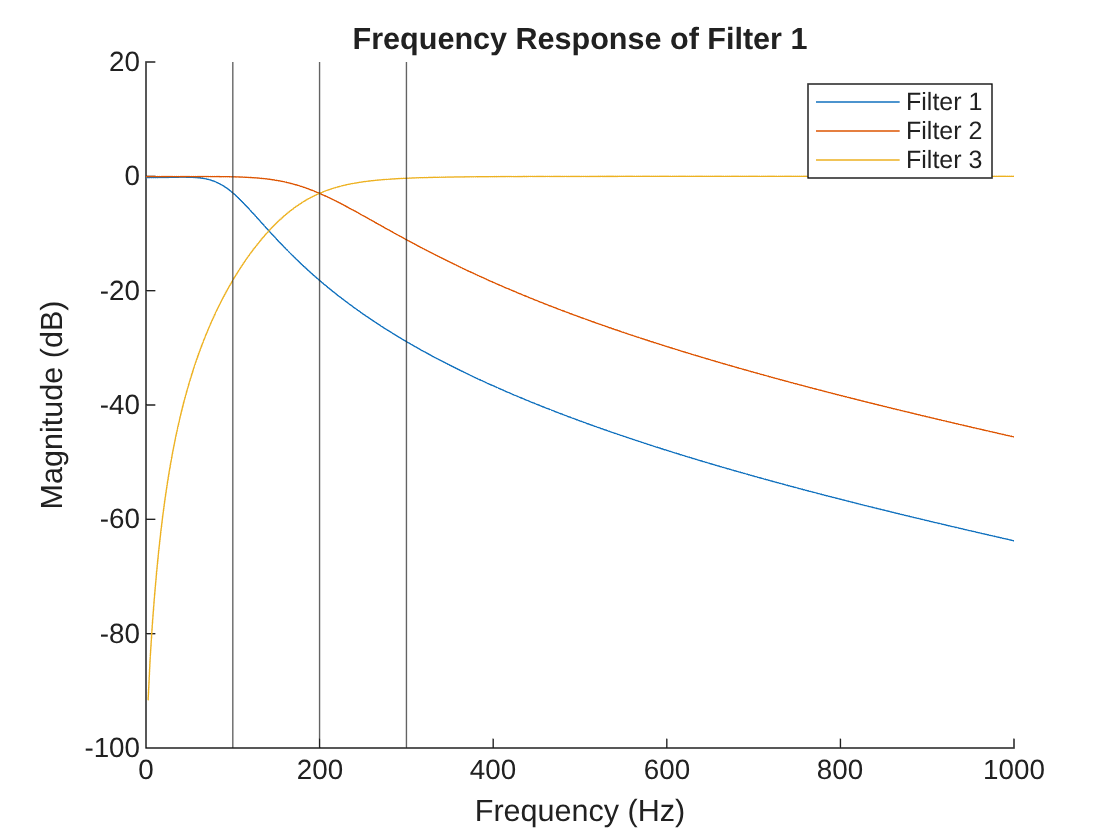

%filter 1
b1 = [2.1961*10^-4 6.5882*10^-4 6.5882*10^-4 2.1961*10^-4]; a1 = [1 -2.7488 2.5282 -0.7776];

%filter 2
b2 = [15.6701*10^-4 47.0103*10^-4 47.0103*10^-4 15.6701*10^-4]; a2 = [1 -2.4986 2.1153 -0.6041];

%filter 3
b3 = [0.7772 -2.3317 2.3317 -0.7772]; a3 = [1 -2.4986 2.1153 -0.6041];

F_s = 5e3;

[h1, f1] = freqz(b1, a1, 1024, F_s);
[h2, f2] = freqz(b2, a2, 1024, F_s);
[h3, f3] = freqz(b3, a3, 1024, F_s);

% Plot the frequency responses of the filters
figure;
hold on;
plot(f1, 20*log10(abs(h1)));
plot(f2, 20*log10(abs(h2)));
plot(f3, 20*log10(abs(h3)));
xlim([0 1000]);
ylim([-100 20]);
xline([100 200 300]);
legend('Filter 1', 'Filter 2', 'Filter 3');
title('Frequency Response of Filter 1');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
hold off;

Opg. 4

clear; clc;
f_l = 90; f_h = 110; F_s = 1e3;

omega_l = (2*pi*f_l)/F_s

omega_l = 0.5655

omega_h = (2*pi*f_h)/F_s

omega_h = 0.6912

n = -50:50;


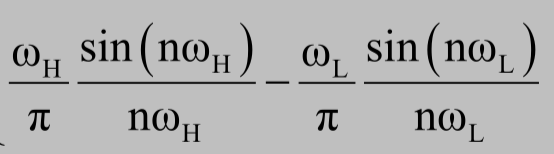

h_p = (omega_h/pi)*sinc(n*omega_h/pi)-(omega_l/pi)*sinc(n*omega_l/pi);

h_p(1)

ans = -2.1058e-17

h_p(6)

ans = -0.0044

h_p(11)

ans = 0.0094

h_p(16)

ans = -0.0147

N_taps = 45;

syms K M
M_value = double(solve(N_taps == M + 1, M))

M_value = 44

K_value = double(solve(N_taps == 2*K + 1, K))

K_value = 22

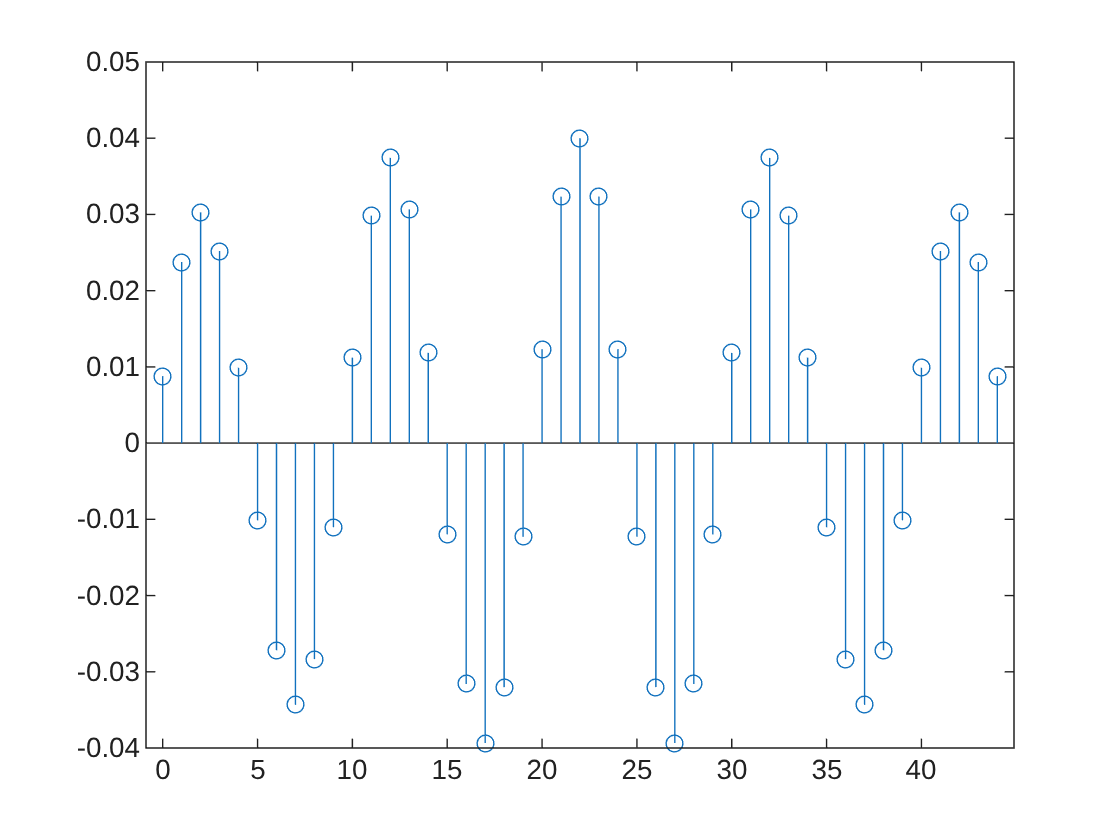

n = -K_value:K_value;

h_bp = (omega_h/pi)*sinc(n*omega_h/pi)-(omega_l/pi)*sinc(n*omega_l/pi);

stem(0:M_value, h_bp)

[H, f] = freqz(h_bp, 1, 1024, F_s);

figure;
plot(f, 20*log10(abs(H)));
ylim([-60 30]);
xline([f_l f_h], 'r');
xline([50 100 150], 'g');
title('Frequency Response of Bandpass Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
legend('Bandpass Filter', 'f_L and f_H', '50, 100, 150 Hz');
hold off;

xlim([-19 481])
ylim([-61.8 28.2])
 
BandpassFilterLine = findobj(gcf, "DisplayName", "Bandpass Filter")

BandpassFilterLine =   Line (Bandpass Filter) with properties:

              Color: [0.0660 0.4430 0.7450]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.4883 0.9766 1.4648 1.9531 2.4414 2.9297 3.4180 3.9062 4.3945 4.8828 5.3711 5.8594 6.3477 6.8359 7.3242 7.8125 8.3008 8.7891 9.2773 9.7656 10.2539 10.7422 11.2305 11.7188 12.2070 12.6953 13.1836 13.6719 14.1602 … ] (1×1024 double)
              YData: [-20.8541 -20.8750 -20.9376 -21.0428 -21.1915 -21.3853 -21.6262 -21.9172 -22.2616 -22.6640 -23.1301 -23.6673 -24.2852 -24.9963 -25.8175 -26.7721 -27.8937 -29.2325 -30.8690 -32.9438 -35.7383 -39.9615 -48.6501 … ] (1×1024 double)

  Show 

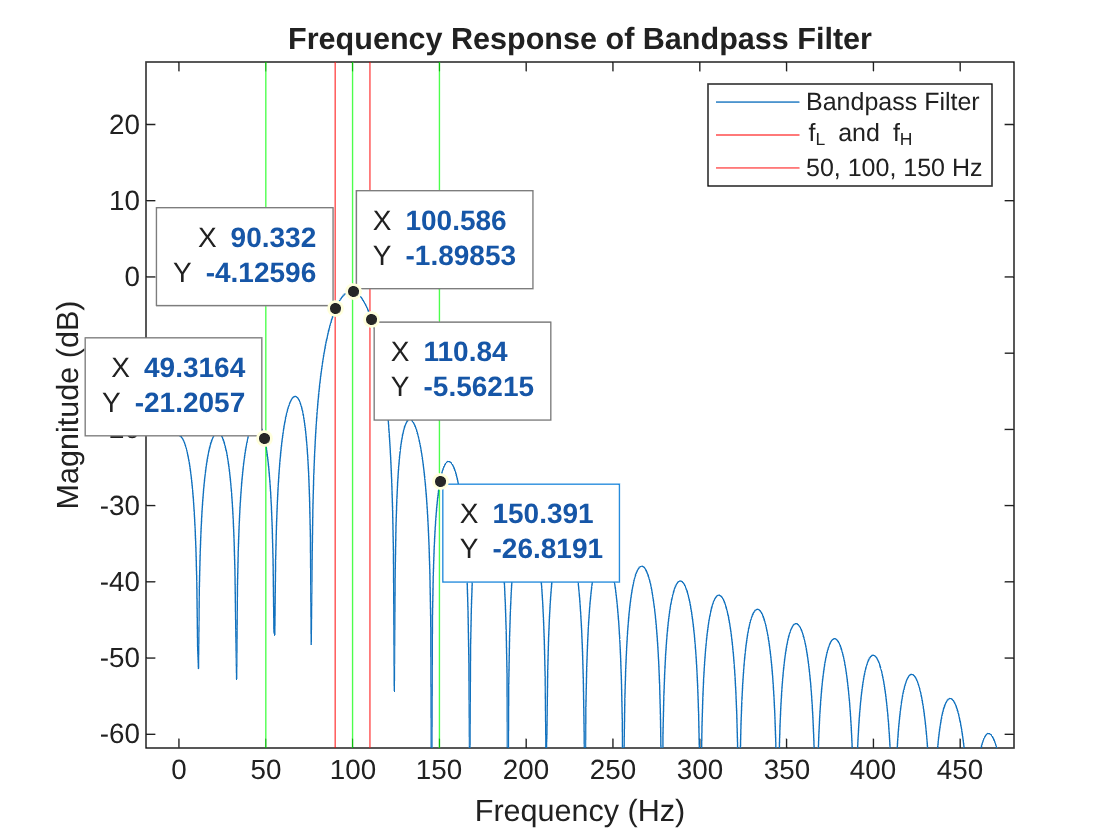

datatip(BandpassFilterLine,49.32,-21.21,"Location","northwest");
datatip(BandpassFilterLine,90.33,-4.126,"Location","northwest");
datatip(BandpassFilterLine,100.6,-1.899);
datatip(BandpassFilterLine,110.8,-5.562,"Location","southeast");
datatip(BandpassFilterLine,150.4,-26.82,"Location","southeast");

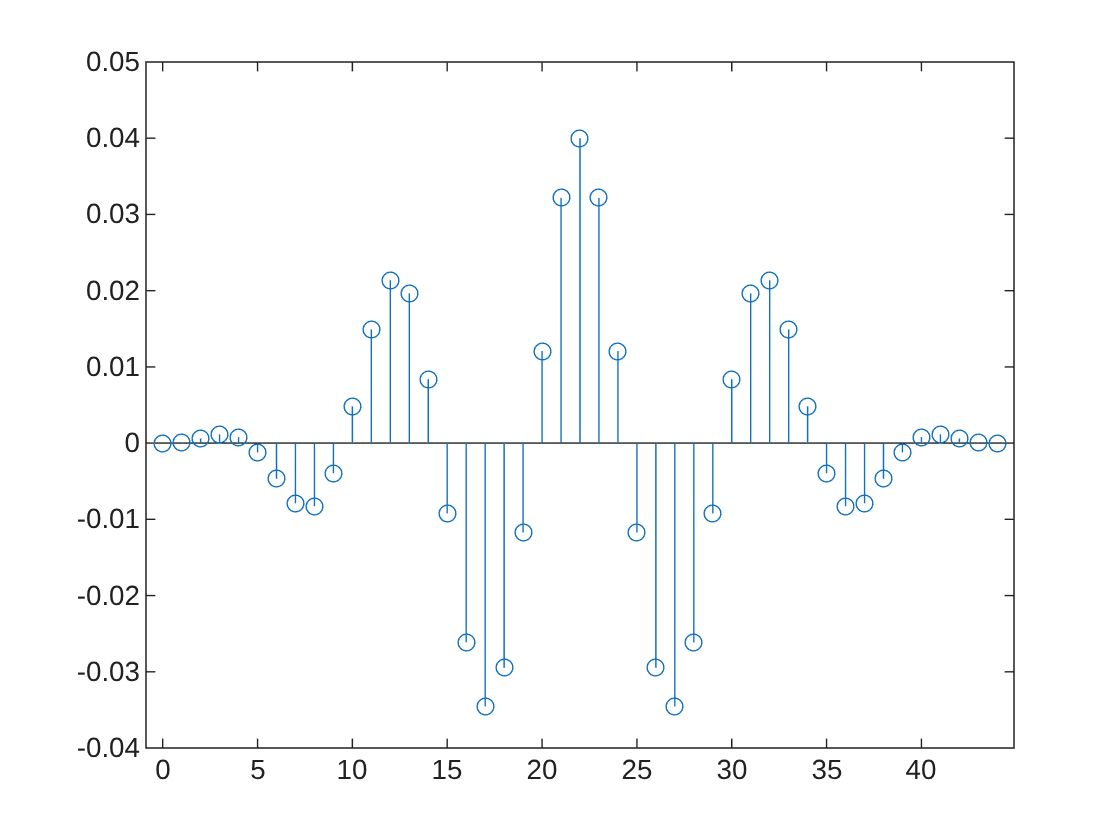

w_hanning = 0.5 - 0.5*cos((2*pi*(0:M_value))/M_value); %window filter is calculated with n = 0..M
h_w = h_bp.*w_hanning;

stem(0:M_value, h_w)

h_w(23)

ans = 0.0400

h_w(28)

ans = -0.0345

h_w(33)

ans = 0.0214

h_w(38)

ans = -0.0079

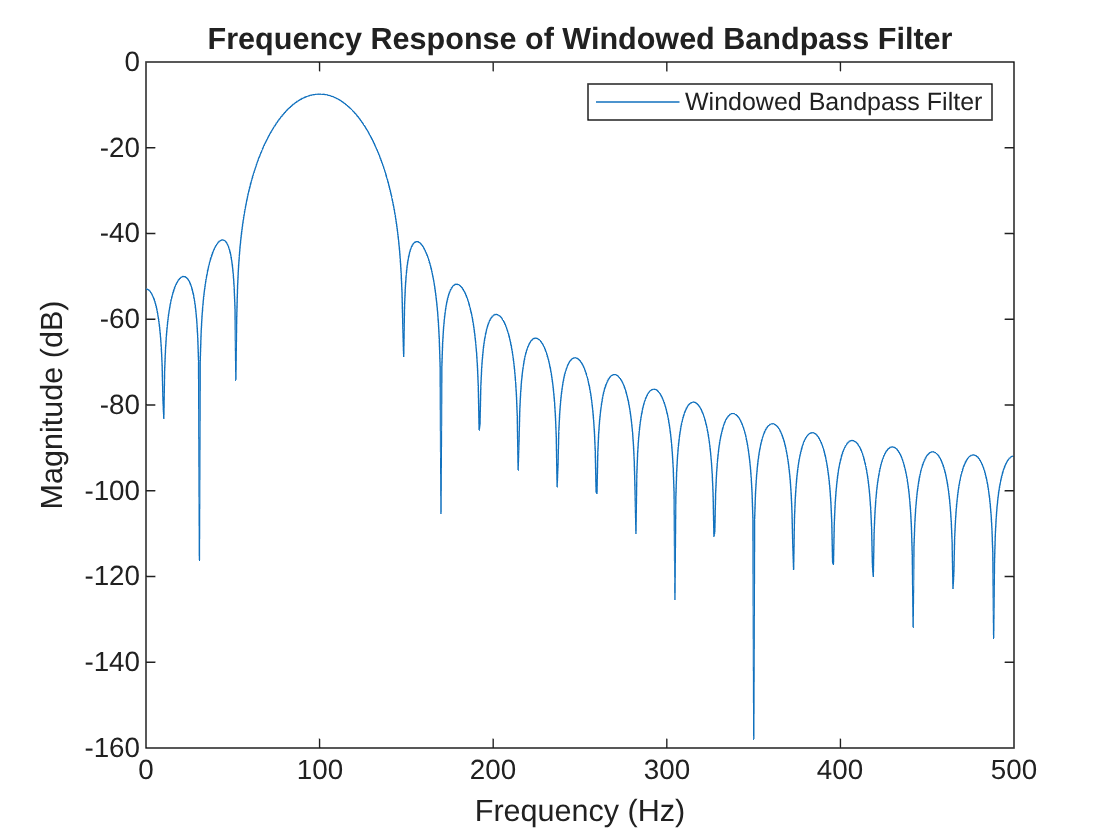

[H_w, f] = freqz(h_w, 1, 1024, F_s);
figure;
plot(f, 20*log10(abs(H_w)));
title('Frequency Response of Windowed Bandpass Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
legend('Windowed Bandpass Filter');
hold off;